**Exercise 1: FTCS Scheme**

Recreate the example from Sanderson's movie:

Use $L = 10$ and $\alpha = 1$. Solve for $t = 0 \to 20$ using $\Delta t = \frac{\Delta t_{max}}{10}$ and $N = 21$, where $\Delta t_{max} = \frac{\Delta x^2}{2\alpha}$.

Initial condition $T(x < 5, t) = 90^{\circ}$ and $T(x \geq 5, t) = 10^{\circ}$.

Solve it using the FTCS scheme

a) Use Dirichlet BCs: $T_{left} = 90^{\circ}, T_{right} = 10^{\circ}$

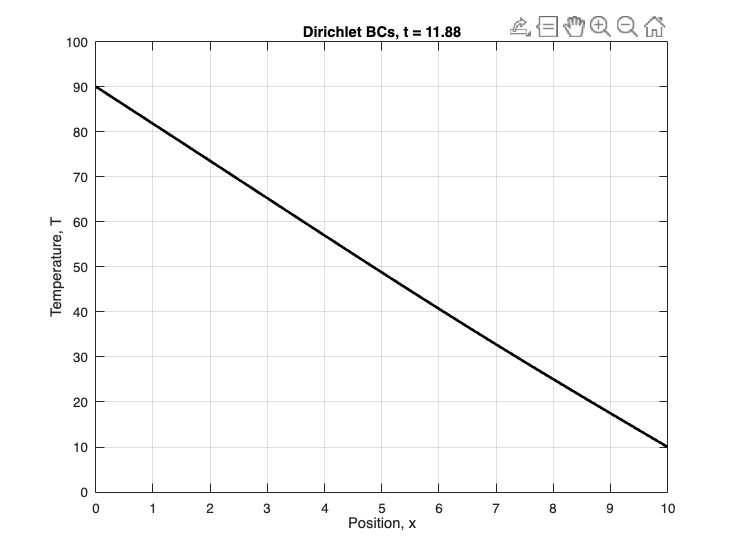

%% Exercise 1a: FTCS scheme with Dirichlet BCs
clc; clear; close all;

% Parameters
L = 10;
alpha = 1;

% Spatial grid
N = 21;
dx = L/(N-1);
x = linspace(0,L,N);

% Time grid
dt_max = dx^2/(2*alpha);
dt = dt_max/10;
t = 0:dt:20;
nt = length(t);

% FTCS constant
C = alpha*dt/dx^2;

% Initialize temperature matrix
T = zeros(N,nt);

% Initial condition:
% T(x < 5,0) = 90, T(x >= 5,0) = 10
T(x < 5,1) = 90;
T(x >= 5,1) = 10;

% Dirichlet boundary conditions
T(1,:) = 90;
T(end,:) = 10;

% Interior nodes
j = 2:N-1;

% FTCS solve
for n = 1:nt-1
    T(j,n+1) = T(j,n) + C*(T(j+1,n) - 2*T(j,n) + T(j-1,n));
end

% Animation
figure;
hp = plot(x,T(:,1),'k','LineWidth',2);
xlabel('Position, x');
ylabel('Temperature, T');
title(sprintf('Dirichlet BCs, t = %.2f', t(1)));
xlim([0 L]);
ylim([0 100]);
grid on;

for n = 1:10:nt
    hp.YData = T(:,n);
    title(sprintf('Dirichlet BCs, t = %.2f', t(n)));
    drawnow;
    pause(0.05);
end

b) Change to Neumann BCs (both ends): $\frac{\partial T}{\partial x} = 0$.

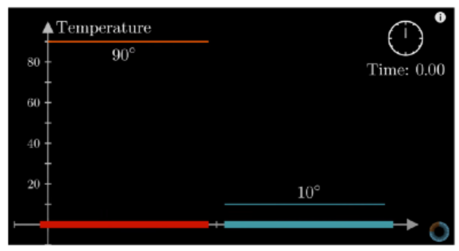

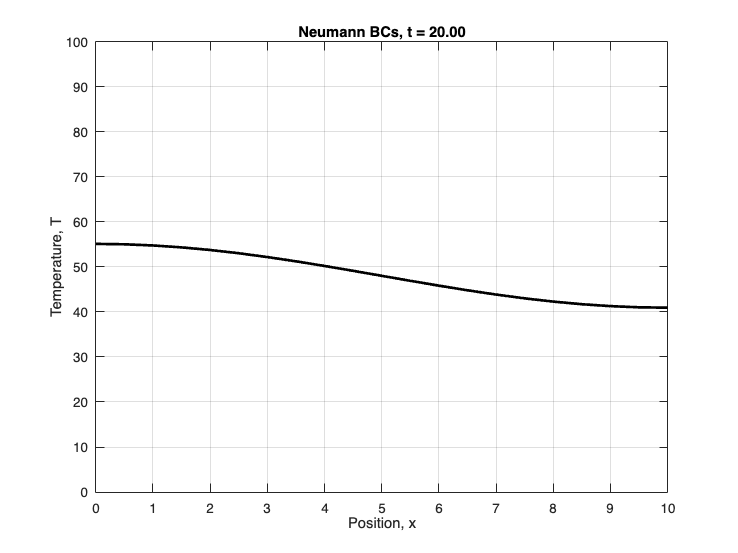

%% Exercise 1b: FTCS scheme with Neumann BCs
clc; clear; close all;

% Parameters
L = 10;
alpha = 1;

% Spatial grid
N = 21;
dx = L/(N-1);
x = linspace(0,L,N);

% Time grid
dt_max = dx^2/(2*alpha);
dt = dt_max/10;
t = 0:dt:20;
nt = length(t);

% FTCS constant
C = alpha*dt/dx^2;

% Initialize temperature matrix
T = zeros(N,nt);

% Initial condition:
% T(x < 5,0) = 90, T(x >= 5,0) = 10
T(x < 5,1) = 90;
T(x >= 5,1) = 10;

% Neumann BC values
Tp_left = 0;
Tp_right = 0;

% Interior nodes
j = 2:N-1;

% FTCS solve
for n = 1:nt-1
    
    % Interior nodes
    T(j,n+1) = T(j,n) + C*(T(j+1,n) - 2*T(j,n) + T(j-1,n));
    
    % Left boundary: dT/dx = 0
    T(1,n+1) = T(1,n) + C*(-2*T(1,n) + 2*T(2,n) - 2*dx*Tp_left);
    
    % Right boundary: dT/dx = 0
    T(end,n+1) = T(end,n) + C*(2*T(end-1,n) - 2*T(end,n) + 2*dx*Tp_right);
end

% Animation
figure;
hp = plot(x,T(:,1),'k','LineWidth',2);
xlabel('Position, x');
ylabel('Temperature, T');
title(sprintf('Neumann BCs, t = %.2f', t(1)));
xlim([0 L]);
ylim([0 100]);
grid on;

for n = 1:10:nt
    hp.YData = T(:,n);
    title(sprintf('Neumann BCs, t = %.2f', t(n)));
    drawnow;
    pause(0.05);
end

**Exercise 2: Semi-Discretization**

Recreate the example from Sanderson's movie:

Use $L = 10$ and $\alpha = 1$. Solve for $t = 0 \to 20$ using $\Delta t = \frac{\Delta t_{max}}{10}$ and $N = 21$, where $\Delta t_{max} = \frac{\Delta x^2}{2\alpha}$.

Initial condition $T(x < 5, t) = 90^{\circ}$ and $T(x \geq 5, t) = 10^{\circ}$.

Repeat Exercise 1, but use the semi-discretization method. Solve the system of equations by Forward Euler, RK4, and ode45 solvers that you already have.

a. Dirichlet BCs at both ends: $T_{left} = 90$ and $T_{right} = 10$

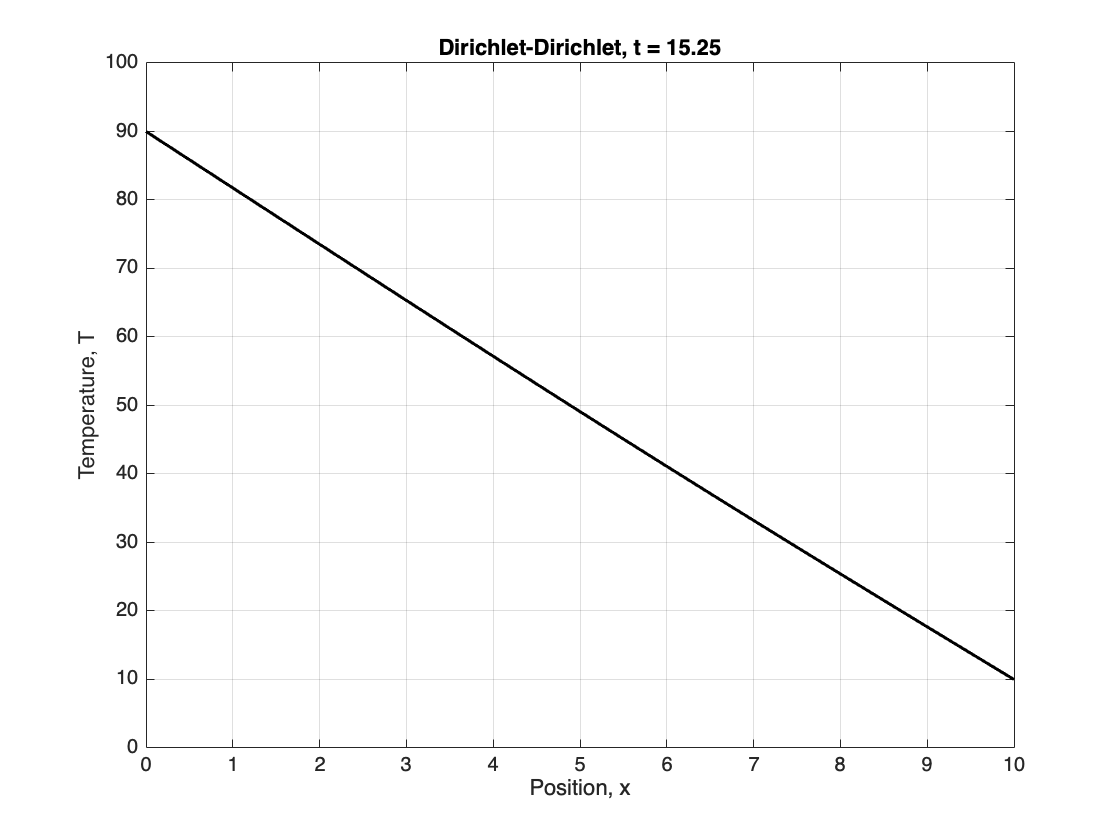

%% Exercise 2a: Semi-discretization with Dirichlet BCs at both ends
clc; clear; close all;

L = 10;
alpha = 1;

nx = 21;
dx = L/(nx-1);
x = linspace(0,L,nx);

i_int = 2:nx-1;

dt_max = dx^2/(2*alpha);
dt = dt_max/10;
t = 0:dt:20;
nt = length(t);

T_left = 90;
T_right = 10;

T = zeros(nx,nt);

T(x < 5,1) = 90;
T(x >= 5,1) = 10;

T(1,:) = T_left;
T(end,:) = T_right;

T0 = T(i_int,1);

T(i_int,:) = odesRK4(@ODEfun_a,T0,t);

figure;
hp = plot(x,T(:,1),'k','LineWidth',1.5);
xlabel('Position, x');
ylabel('Temperature, T');
ylim([0 100]);
xlim([0 L]);
grid on;
ht = title(['Dirichlet-Dirichlet, t = ' num2str(t(1))]);


for n = 1:20:nt
    hp.YData = T(:,n);
    ht.String = ['Dirichlet-Dirichlet, t = ' num2str(t(n))];
    drawnow;
    pause(0.05);
end

function f = ODEfun_a(T_ins, t)
alpha = 1;
L = 10;
nx = 21;
dx = L/(nx-1);
c = alpha/dx^2;

T_left = 90;
T_right = 10;

nB = nx - 2;
D1 = ones(nB-1,1);
B = -2*eye(nB) + diag(D1,1) + diag(D1,-1);

b = zeros(nB,1);
b(1) = T_left;
b(end) = T_right;

f = c*(B*T_ins + b);
end

function f = ODEfun45_a(t, T_ins)
alpha = 1;
L = 10;
nx = 21;
dx = L/(nx-1);
c = alpha/dx^2;

T_left = 90;
T_right = 10;

nB = nx - 2;
D1 = ones(nB-1,1);
B = -2*eye(nB) + diag(D1,1) + diag(D1,-1);

b = zeros(nB,1);
b(1) = T_left;
b(end) = T_right;

f = c*(B*T_ins + b);
end

b. Neumann BCs at both ends: $T'_{left} = 0$ and $T'_{right} = 0$

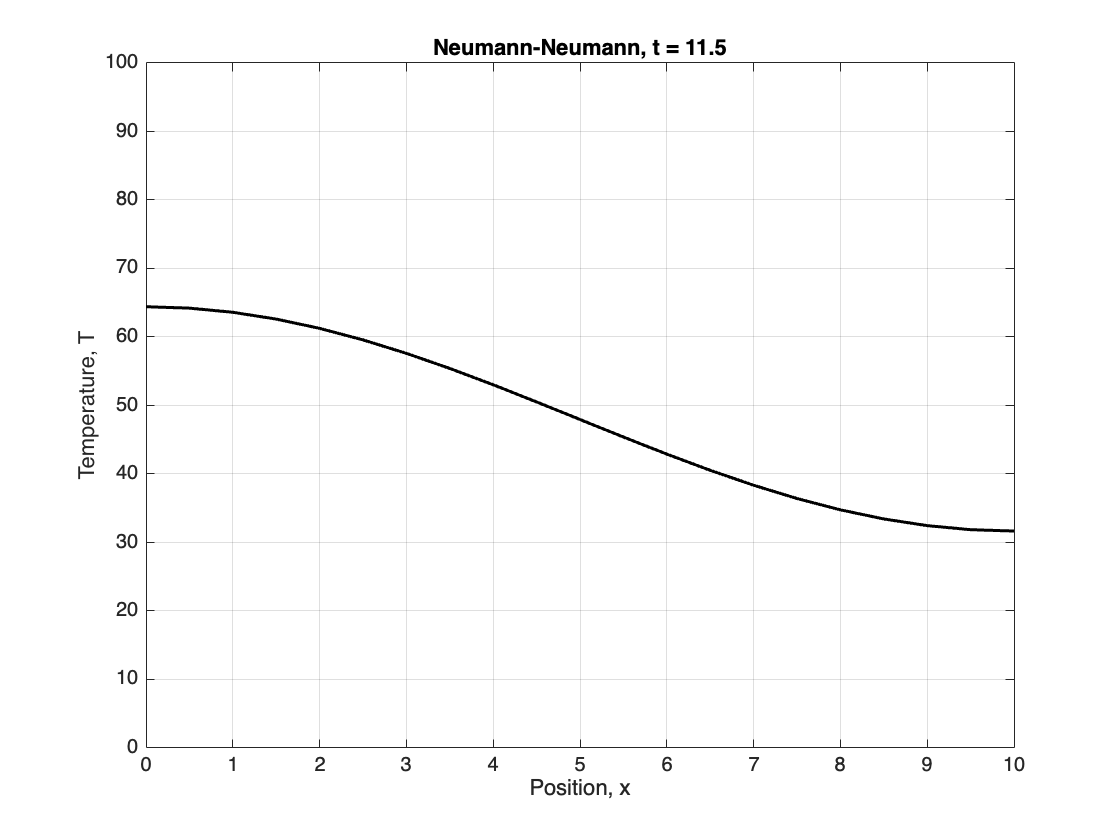

%% Exercise 2b: Semi-discretization with Neumann BCs at both ends
clc; clear; close all;

L = 10;
alpha = 1;

nx = 21;
dx = L/(nx-1);
x = linspace(0,L,nx);

i_int = 1:nx;

dt_max = dx^2/(2*alpha);
dt = dt_max/10;
t = 0:dt:20;
nt = length(t);

Tp_left = 0;
Tp_right = 0;

T = zeros(nx,nt);

T(x < 5,1) = 90;
T(x >= 5,1) = 10;

T0 = T(i_int,1);

T(i_int,:) = odesRK4(@ODEfun_b,T0,t);

figure;
hp = plot(x,T(:,1),'k','LineWidth',1.5);
xlabel('Position, x');
ylabel('Temperature, T');
ylim([0 100]);
xlim([0 L]);
grid on;
ht = title(['Neumann-Neumann, t = ' num2str(t(1))]);


for n = 1:20:nt
    hp.YData = T(:,n);
    ht.String = ['Neumann-Neumann, t = ' num2str(t(n))];
    drawnow;
    pause(0.05);
end

function f = ODEfun_b(T_ins, t)
alpha = 1;
L = 10;
nx = 21;
dx = L/(nx-1);
c = alpha/dx^2;

Tp_left = 0;
Tp_right = 0;

nB = nx;
D1 = ones(nB-1,1);
B = -2*eye(nB) + diag(D1,1) + diag(D1,-1);
b = zeros(nB,1);

B(1,2) = 2;
B(end,end-1) = 2;

b(1) = -2*dx*Tp_left;
b(end) = 2*dx*Tp_right;

f = c*(B*T_ins + b);
end

function f = ODEfun45_b(t, T_ins)
alpha = 1;
L = 10;
nx = 21;
dx = L/(nx-1);
c = alpha/dx^2;

Tp_left = 0;
Tp_right = 0;

nB = nx;
D1 = ones(nB-1,1);
B = -2*eye(nB) + diag(D1,1) + diag(D1,-1);
b = zeros(nB,1);

B(1,2) = 2;
B(end,end-1) = 2;

b(1) = -2*dx*Tp_left;
b(end) = 2*dx*Tp_right;

f = c*(B*T_ins + b);
end

c. Dirichlet BCs at beginning and Neumann at end of domain: $T_{left} = 90$ and $T'_{right} = 0$

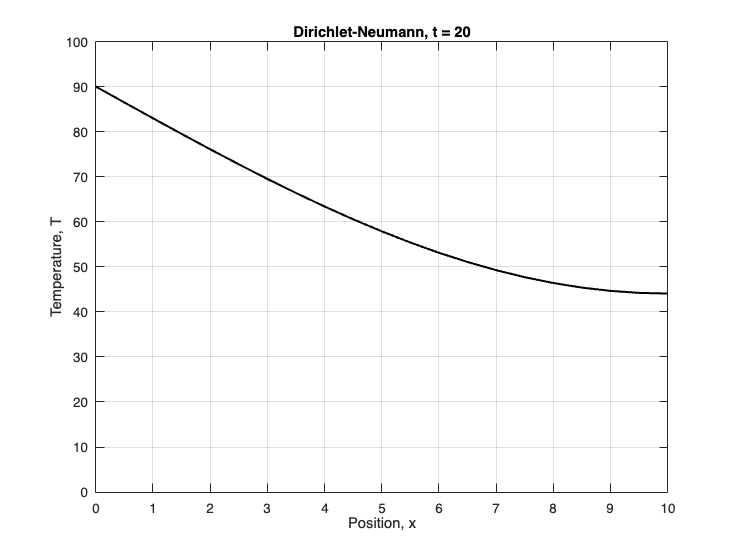

%% Exercise 2c: Semi-discretization with Dirichlet left and Neumann right
clc; clear; close all;

L = 10;
alpha = 1;

nx = 21;
dx = L/(nx-1);
x = linspace(0,L,nx);

i_int = 2:nx;

dt_max = dx^2/(2*alpha);
dt = dt_max/10;
t = 0:dt:20;
nt = length(t);

T_left = 90;
Tp_right = 0;

T = zeros(nx,nt);

T(x < 5,1) = 90;
T(x >= 5,1) = 10;

T(1,:) = T_left;

T0 = T(i_int,1);

T(i_int,:) = odesRK4(@ODEfun_c,T0,t);

figure;
hp = plot(x,T(:,1),'k','LineWidth',1.5);
xlabel('Position, x');
ylabel('Temperature, T');
ylim([0 100]);
xlim([0 L]);
grid on;
ht = title(['Dirichlet-Neumann, t = ' num2str(t(1))]);

for n = 1:20:nt
    hp.YData = T(:,n);
    ht.String = ['Dirichlet-Neumann, t = ' num2str(t(n))];
    drawnow;
    pause(0.05);
end


function f = ODEfun_c(T_ins, t)
alpha = 1;
L = 10;
nx = 21;
dx = L/(nx-1);
c = alpha/dx^2;

T_left = 90;
Tp_right = 0;

nB = nx - 1;
D1 = ones(nB-1,1);
B = -2*eye(nB) + diag(D1,1) + diag(D1,-1);
b = zeros(nB,1);

b(1) = T_left;
B(end,end-1) = 2;
b(end) = 2*dx*Tp_right;

f = c*(B*T_ins + b);
end

function f = ODEfun45_c(t, T_ins)
alpha = 1;
L = 10;
nx = 21;
dx = L/(nx-1);
c = alpha/dx^2;

T_left = 90;
Tp_right = 0;

nB = nx - 1;
D1 = ones(nB-1,1);
B = -2*eye(nB) + diag(D1,1) + diag(D1,-1);
b = zeros(nB,1);

b(1) = T_left;
B(end,end-1) = 2;
b(end) = 2*dx*Tp_right;

f = c*(B*T_ins + b);
end